# **InverseJacobiCS**

[Inverse of the Jacobi elliptic function cs](https://dlmf.nist.gov/22.15)

## Definition


$${\textrm{cs}}^{-1} \left(x\left|m\right.\right)\equiv \left\lbrace \begin{array}{cc}
\mathit{\mathbf{F}}\left(\frac{1}{\sqrt{1+x^2 }}\left|m\right.\right) & m\le 1\\
\frac{{\textrm{ds}}^{-1} \left(x/\sqrt{m}\left|m^{-1} \right.\right)}{\sqrt{m}} & m>1
\end{array}\right.$$



$${\mathrm{cs}}^{-1} \left(x,k\right)\equiv {\mathrm{cs}}^{-1} \left(x\left|k^2 \right.\right)$$


where *m *is the parmeter, *k *is the modulus, $\mathit{\mathbf{F}}\left(x\left|m\right.\right)$ is  Jacobi form of the elliptic integral of the first kind.

Domain:   If $-\infty <m\le 1$ then $-\infty \le x\le \infty$ . If $m>1$ then $\sqrt{m-1}<x<\infty$.For the specified domain, the  codomain  is the set of real numbers.

Basic features:

${\mathrm{cs}}^{-1} \left(-x\left|m\right.\right)=-{\mathrm{cs}}^{-1} \left(x\left|m\right.\right)$   (odd)

Special values:

${\mathrm{cs}}^{-1} \left(-\infty \left|m\right.\right)=0$,    ${\mathrm{cs}}^{-1} \left(0\left|m\right.\right)=\mathrm{NaN}$,    ${\mathrm{cs}}^{-1} \left(1\left|\infty \right.\right)=0$

${\mathrm{cs}}^{-1} \left(x\left|0\right.\right)={\mathrm{cot}}^{-1} x$,    ${\mathrm{cs}}^{-1} \left(x\left|1\right.\right)={\mathrm{csch}}^{-1} x$

Identities:


$${\mathrm{cs}}^{-1} \left(\mathrm{cs}\left(x\left|m\right.\right)\left|m\right.\right)=x,\;\;\;\;\left|x\right|<K\left(m\right)$$



$$\textrm{cs}\left({\textrm{cs}}^{-1} \left(x\left|m\right.\right)\left|m\right.\right)=x$$


$K\left(m\right)$ is the complete elliptic integral of the first kind.

## Syntax

Y = InverseJacobiCS(X,K)

y = ijcs(x,k)

Y = mInverseJacobiCS(X,M)

y = mijcs(x,m)

## Description

**Y = InverseJacobiCS(X,K)** return${\;\mathrm{cs}}^{-1} \left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the scse size or any of them can be scalar. **InverseJacobiCS** is the wrapper function which calls the functions **ijcs** element-wise via the function **ufun2**.

**y = ijcs(x,k)** return the value of ${\mathrm{cs}}^{-1} \left(x,k\right)$ for argument *x* and the modulus k. It is assumed that the input arguments are real scalars without check. y is NaN if any of   the input arguments is invalid or convergence failed. **ijcs** is the wrapper function which calls the functions **mijcs**.

**Y = mInverseJacobiCS(X,M)** returns ${\mathrm{cs}}^{-1} \left(x\left|m\right.\right)$ for each element of the arrays X and M (parcseter). X and M must be real and the scse size or any of them can be scalar. **mInverseJacobiCS** is the wrapper function which calls the functions **mijcs** element-wise via the function **ufun2**.

**y = mijcs(x,m)** compute value of ${\mathrm{cs}}^{-1} \left(x\left|m\right.\right)$ for  argument x and the parcseter m. It is assumed that the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed.  **mijcs **call the function **melF **for calculation of ${\mathrm{cs}}^{-1} \left(x\left|m\right.\right)$.

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5;
x = 0.5;
[ijcs(x,k), InverseJacobiCS(x,k), mijcs(x,k^2), mInverseJacobiCS(x,k^2)]

ans =    1.156321727760690   1.156321727760690   1.156321727760690   1.156321727760690


% Maple 1.156321727760690_22


Accuracy.

fprintf('%.16g\n',mijcs(0.5,-4)) 

0.7959506708431314


%  Maple  0.7959506708431313_30

Special values

m=0.5;
disp(mijcs(0,m))  % m < 1 !!!

   NaN



disp(mijcs(1,m)-melF(1/sqrt(2),m))

     0



x=0.5;
disp(mijcs(x,0) - acot(x)) 

     0



disp(mijcs(x,1) - acsch(x))

     0



Identities

m = -2;
x = 0.5; % |x| <= 1
disp(mJacobiCS(mInverseJacobiCS(x,m),m)-x)

     5.551115123125783e-16




k = 0.99995;
x = 0.9999*elK(k);
disp(InverseJacobiCS(JacobiCS(x,k),k)-x)

     3.389999392311438e-11



m = 2; % m>1
x = 2; % x > sqrt(m-1)
disp(mijcs(x,m)-mijds(x/sqrt(m),1/m)/sqrt(m))

     0



m = 0.5;
x = 0.2;
disp(mijcs(-x,m)+mijcs(x,m))

     0



**Vector input**

m = [0.1, 0.5, 0.89, 0.99995];
x = 0.2*ones(size(m));
disp(mJacobiCS(mInverseJacobiCS(x,m),m)-x)

   1.0e-15 *

   0.444089209850063   0.305311331771918   0.222044604925031   0.277555756156289



**Matrix input**

m = [0.1, 0.5, 0.89; -1, -97, 0.99995 ]';
x = 0.2*ones(size(m));
disp(mJacobiCS(mInverseJacobiCS(x,m),m)-x)

   1.0e-14 *

   0.044408920985006  -0.005551115123126
   0.030531133177192   0.111022302462516
   0.022204460492503   0.027755575615629



## **Plot **

**Example 1**

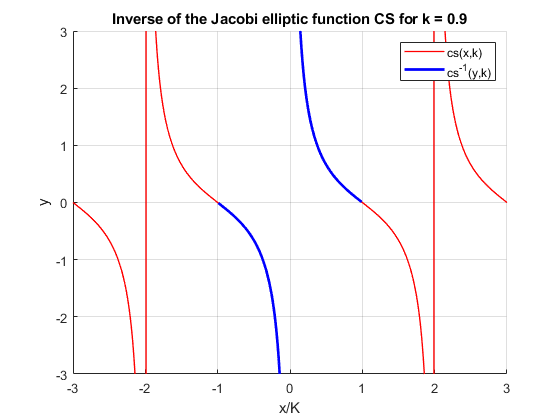

figure
hold on
x=-3:0.01:3;
k = 0.9;
M = elK(k);
plot(x,JacobiCS(M*x,k),'LineWidth',1.0,'Color','red')
x=-12:0.01:12;
plot(InverseJacobiCS(x,k)/M,x,'LineWidth',2,'Color','blue')
legend('cs(x,k)','cs^{-1}(y,k)') %,'Position','best')
xlabel('x/K')
ylabel('y')
%xlim([-1.1 1.1])
ylim([-3 3])
title(sprintf('Inverse of the Jacobi elliptic function CS for k = %g',k))
grid on
hold off

**Example 2**

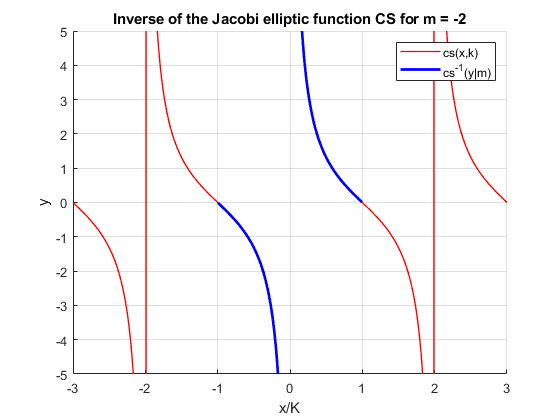

figure
hold on
x=-3:0.01:3;
m = -2;
if m < 1
    M = melK(m);
    xlabel('x/K')
elseif m > 1
    M = melK(1/m)/sqrt(m);
    xlabel('x/K')
else
    M = 1;
    xlabel('x')
end
plot(x,mJacobiCS(M*x,m),'LineWidth',1.0,'Color','red')
x=-12:0.01:12;
plot(mInverseJacobiCS(x,m)/M,x,'LineWidth',2,'Color','blue')
legend('cs(x,k)','cs^{-1}(y|m)') %,'Position','best')
ylabel('y')
%xlim([-1.1 1.1])
ylim([-5 5])
title(sprintf('Inverse of the Jacobi elliptic function CS for m = %g',m))
grid on
hold off

**Example 2**

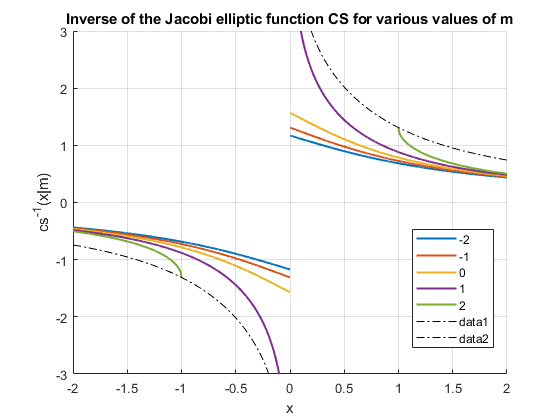

figure
hold on
X = -2:0.001:2;
M = [-2,-1,0,1,2];
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mInverseJacobiCS(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) -3 3])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Inverse of the Jacobi elliptic function CS for various values of m')
N=1:0.01:10;
X = sqrt(N-1);
plot(X,mInverseJacobiCS(X,N),'k-.')
plot(-X,-mInverseJacobiCS(X,N),'k-.')
xlabel('x')
ylabel('cs^{-1}(x|m)')

**Example 3**

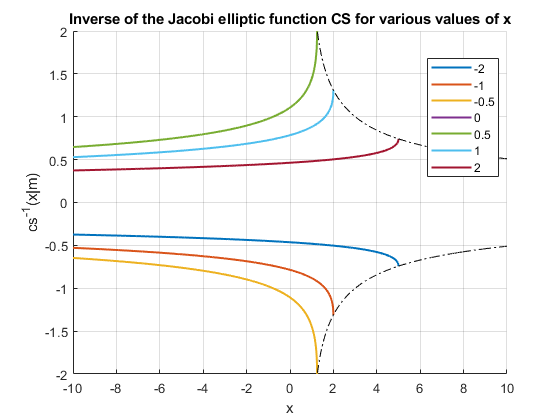

figure
hold on
M = -10:0.01:10;
X = [-2,-1,-0.5,0,0.5,1,2];
SN = zeros(length(X),length(M));
clg{length(X)}=[];
for i = 1:length(X)
     clg{i} = num2str(X(i));
    SN(i,:) = mInverseJacobiCS(X(i),M);
end
plot(M,SN,'LineWidth',1.5)
axis([min(M) max(M) -3 3])
ylim([-2  2])
grid on
legend(clg{1:length(X)},'Location','Best')
title('Inverse of the Jacobi elliptic function CS for various values of x')
xlabel('x')
ylabel('cs^{-1}(x|m)')
M = 1:0.01:10;
F = mInverseJacobiCS(sqrt(N-1),M);
plot(M,F,'k-.')
plot(M,-F,'k-.')
hold off

**Example 4**

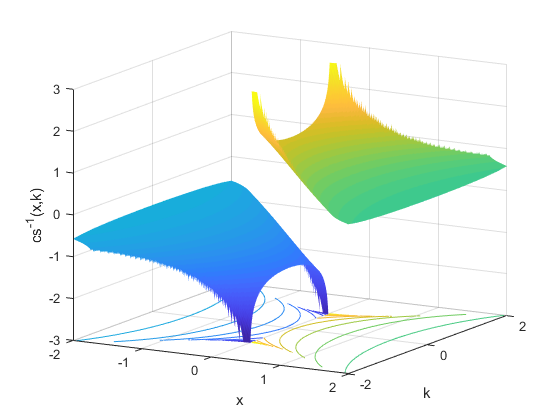

figure
x=-2:0.01:2;
k=-2:0.01:2;
zz = 3;
[X,M]=meshgrid(x,k);
hs=surfc(X,M,InverseJacobiCS(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -zz;
hc.LineWidth = 0.5;
hc.LevelList = -zz:zz/10:zz;
view([30 15])
caxis([-zz zz])
xlabel('x')
ylabel('k')
zlabel('cs^{-1}(x,k)')
zlim([-zz zz])
grid on

**Example 4**

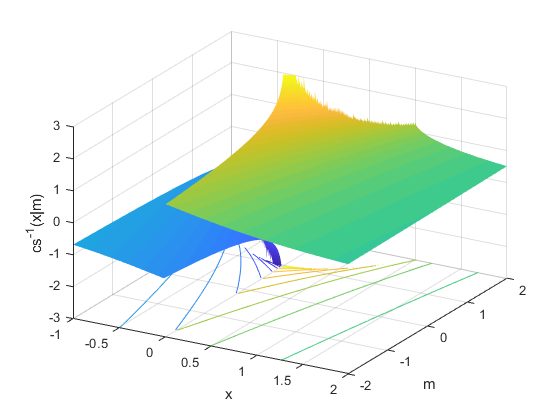

figure
x=-1:0.01:2;
m=-2:0.01:2;
zz = 3;
[X,M]=meshgrid(x,m);
hs=surfc(X,M,mInverseJacobiCS(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -zz;
hc.LineWidth = 0.5;
hc.LevelList = -zz:zz/10:zz;
view([30 30])
caxis([-zz zz])
xlabel('x')
ylabel('m')
zlabel('cs^{-1}(x|m)')
zlim([-zz zz])
grid on

**Example 5**

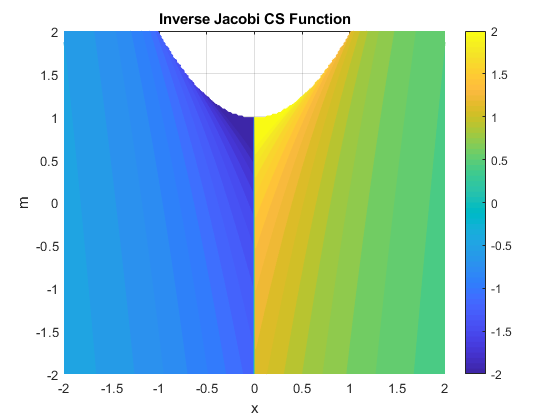

figure
f = @(x,m)mInverseJacobiCS(x,m);
fcontour(f,[-2 2 -2 2],'Fill','on','LevelList',-2:0.1:2,'MeshDensity',200)
title('Inverse Jacobi CS Function')
colorbar
xlabel('x')
ylabel('m')
grid on

**Example 6**

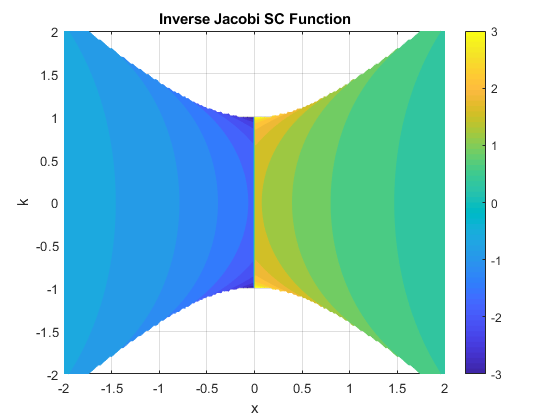

figure
f = @(x,k)InverseJacobiCS(x,k);
fcontour(f,[-2 2 -2 2],'Fill','on','LevelList',-3:0.3:3,'MeshDensity',200)
title('Inverse Jacobi SC Function')
colorbar
xlabel('x')
ylabel('k')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/22)

[Jacobi elliptic functions, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **References**

## See Also